# Conditional Areal-to-point exemple with actual data.

addpath(genpath('./.'));  % Add folder and sub-folder to path
clear all; close all
load('result-A2PK/GEN-Run_1_2017-05-07_14-37');

Define the synthetic case study

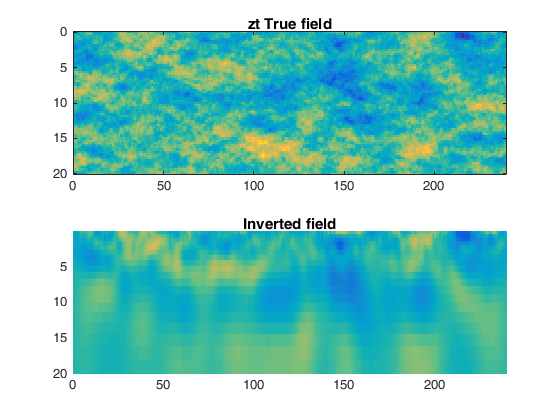

[kern.prior,kern.axis_prim] = ksdensity(sigma_true(:));
parm.nscore=1;
Nscore = nscore(kern, parm, 0);
NSigma.x=Sigma.x_raw; NSigma.y=Sigma.y_raw; 
[NSigma.X, NSigma.Y] = meshgrid(Sigma.x_raw, Sigma.y_raw);
d = reshape(Nscore.forward(Sigma.d_raw(:)) ,numel(NSigma.y),numel(NSigma.x));
zt = reshape(Nscore.forward(sigma_true(:)), grid_gen.ny, grid_gen.nx);
c_axis=[ min(zt(:)) max(zt(:)) ];
subplot(2,1,1);imagesc(grid_gen.x, grid_gen.y, zt); caxis(c_axis); title('zt True field');
subplot(2,1,2); surf(NSigma.x, NSigma.y, d,'EdgeColor','none'); caxis(c_axis); title('Inverted field'); view(2); axis tight; set(gca,'Ydir','reverse'); box on

Built the matrix G which link the true variable zt to the measured coarse scale d

G = zeros(numel(NSigma.X),grid_gen.nxy);
for ij=1:grid_gen.nxy
     [~,id_z]=min((grid_gen.X(ij)-NSigma.X(:)).^2 + (grid_gen.Y(ij)-NSigma.Y(:)).^2);
     G(id_z,ij)=1;%/(NSigma.dx*NSigma.dy);
end
for ij = 1:numel(NSigma.X)
    G(ij,G(ij,:)==1) = 1 ./ sum(G(ij,:)==1);
end

Sample zt

zt_pt = sampling_pt(grid_gen,zt,2,10);

Kriging prediction

Cz = covardm_perso([grid_gen.X(:) grid_gen.Y(:)], [grid_gen.X(:) grid_gen.Y(:)], gen.covar);
Czd = Cz * G';
Cd = G * Czd;

Czh = covardm_perso([zt_pt.x(:) zt_pt.y(:)], [zt_pt.x(:) zt_pt.y(:)], gen.covar);
Czzh = covardm_perso([grid_gen.X(:) grid_gen.Y(:)], [zt_pt.x(:) zt_pt.y(:)], gen.covar);

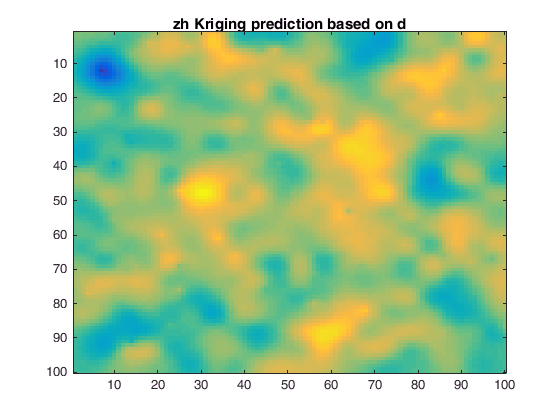

Czhd = Czd(zt_pt.id,:);

CCa = [ Cd Czhd' ; Czhd Czh ];
CCb = [ Czd' ; Czzh' ];

W=zeros(grid_gen.nxy,numel(NSigma.X)+zt_pt.n);
for ij=1:grid_gen.nxy
    W(ij,:) = CCa \ CCb(:,ij);
end
zh = reshape( W * [d(:) ; zt_pt.d(:)], grid_gen.ny,grid_gen.nx);

imagesc(grid_gen.x, grid_gen.y, zh); caxis(c_axis); title('zh Kriging prediction based on d');

Build unconditional realization

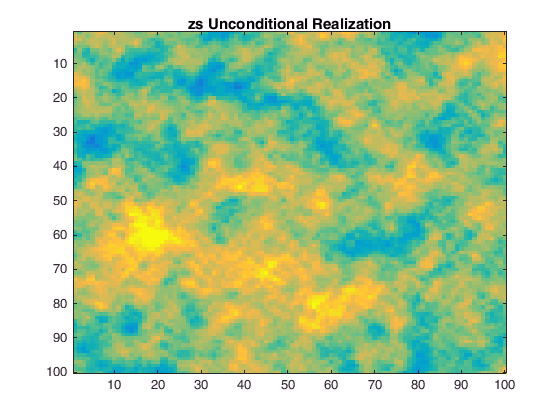

zs = fftma_perso(gen.covar, grid_gen);
imagesc(grid_gen.x, grid_gen.y, zs); caxis(c_axis); title('zs Unconditional Realization');

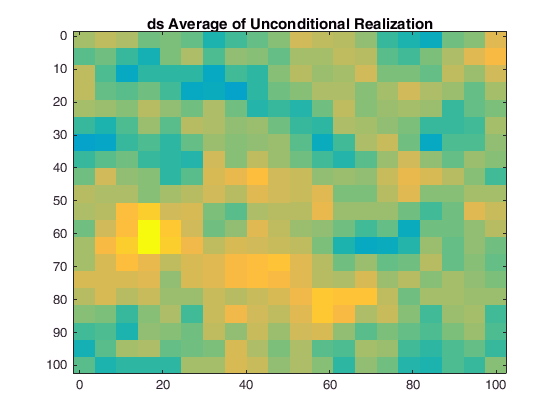

ds = reshape(G * zs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, ds); caxis(c_axis); title('ds Average of Unconditional Realization');

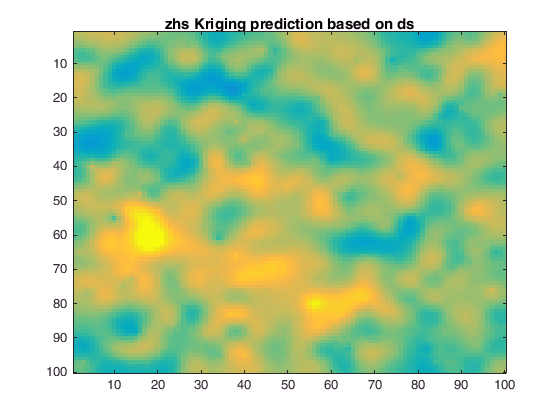

zhs = reshape( W * [ds(:) ; zs(zt_pt.id)'], grid_gen.ny,grid_gen.nx);
imagesc(grid_gen.x, grid_gen.y, zhs); caxis(c_axis); title('zhs Kriging prediction based on ds');

Build condtional realization

zcs = zh + (zs - zhs);

Undefined function or variable 'zh'.


imagesc(grid_gen.x, grid_gen.y, zcs); caxis(c_axis); title('zcs Conditionale Realization');
dcs = reshape(G * zcs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, dcs); caxis(c_axis); title('dcs Average of Conditional Realization');
